Mina värden

a=-2

a = -2

b=2

b = 2

n=4

n = 4


dx=(b-a)/n

dx = 1


L_sum=(1+exp(1)+exp(2)+exp(3))/exp(2)

L_sum = 4.2215


U_sum=(1+exp(1)+exp(2)+exp(3))/exp(1)

U_sum = 11.4752

Standard uppgift

% Computes Riemann sums for the exponential function

a=1;                        % Left limit of integration
b=2;                        % Right limit of integration
n=3;                        % Antal delintervall/number of subintervals

dx=(b-a)/n;                 % width of subinterval
P=linspace(a,b,n+1);        % Partition P=[x_0 x_1 x_2 ... x_n]

% Evaluation of function e^x
fleft=exp(P(1:end-1));      % e^x in points x_{i-1}
fright=exp(P(2:end));       % e^x in points x_i

% Riemann sums (assumes increasing or decreasing function)
Rleft=sum(fleft)*dx;        % L if increasing function, U if decreasing         
Rright=sum(fright)*dx;      % U if increasing function, L if decreasing

L=min(Rleft,Rright);        % Lower Riemann sum
U=max(Rleft,Rright);        % Upper Riemann sum

disp(' ');

disp(['L(f,P)=' num2str(L)]);

L(f,P)=3.9355


disp(['U(f,P)=' num2str(U)]);

U(f,P)=5.4924


disp(' ');

Mina värden i uppgiften

% Computes Riemann sums for the exponential function

a=-2;                        % Left limit of integration
b=2;                        % Right limit of integration
n=4;                        % Antal delintervall/number of subintervals

dx=(b-a)/n;                 % width of subinterval
P=linspace(a,b,n+1);        % Partition P=[x_0 x_1 x_2 ... x_n]

% Evaluation of function e^x
fleft=exp(P(1:end-1));      % e^x in points x_{i-1}
fright=exp(P(2:end));       % e^x in points x_i

% Riemann sums (assumes increasing or decreasing function)
Rleft=sum(fleft)*dx;        % L if increasing function, U if decreasing         
Rright=sum(fright)*dx;      % U if increasing function, L if decreasing

L=min(Rleft,Rright);        % Lower Riemann sum
U=max(Rleft,Rright);        % Upper Riemann sum

disp(' ');

disp(['L(f,P)=' num2str(L)]);

L(f,P)=4.2215


disp(['U(f,P)=' num2str(U)]);

U(f,P)=11.4752


disp(' ');

Större n

% Computes Riemann sums for the exponential function

a=-2;                        % Left limit of integration
b=2;                        % Right limit of integration
n=1000;                        % Antal delintervall/number of subintervals

dx=(b-a)/n;                 % width of subinterval
P=linspace(a,b,n+1);        % Partition P=[x_0 x_1 x_2 ... x_n]

% Evaluation of function e^x
fleft=exp(P(1:end-1));      % e^x in points x_{i-1}
fright=exp(P(2:end));       % e^x in points x_i

% Riemann sums (assumes increasing or decreasing function)
Rleft=sum(fleft)*dx;        % L if increasing function, U if decreasing         
Rright=sum(fright)*dx;      % U if increasing function, L if decreasing

L=min(Rleft,Rright);        % Lower Riemann sum
U=max(Rleft,Rright);        % Upper Riemann sum

disp(' ');

disp(['L(f,P)=' num2str(L)]);

L(f,P)=7.2392


disp(['U(f,P)=' num2str(U)]);

U(f,P)=7.2682


disp(' ');

L och U verkar konvergera mot I

Riemann(@exp,-2,2,0.001)

ans = 7.2537

x=-5:0.1:5

x =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


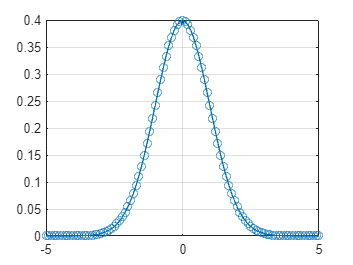

plot(x,normfunk(x),"o-")
grid on

Ser ut att vara ungefär 1 a.e.

Arean borde vara 1 och halva arean blor då 0.5

Test=Riemann(@normfunk,1,2,0.01)

Test = 0.1359

Det som gör det problematiskt att använda @Riemann är den lägre integrationsgränsen -inf

Men funktionen är jämn(symmetrisk) och kan därför uppskattas att 0.5 a.e. ligger på intervallet (-inf,0).

Byt helt enkelt ut den lägre integrationsgränsen mot 0 och addera 0.5 till funktionen.

Problemet kan nu lösas med detta:

Norm_044=Riemann(@normfunk,0,0.44,0.00001)+0.5

Norm_044 = 0.6700

Detta värde stämmer överrens med värdet i tabellen.